filename1 = "y_test.csv";
table1 = readtable(filename1);
test = table2array(table1)

filename = "y_pred.csv";
table = readtable(filename);
pred_raw = table2array(table)

pred_filt = zeros(size(pred_raw));
pred_env = zeros(size(pred_raw))
fc = 10;
fs = 2000;
[b,a] = butter(2,fc/(fs/2),"low")

for i = 1:5
    pred_filt(:,i) = filter(b,a,pred_raw(:,i));
    [x,pred_env(:,i)] = envelope(pred_raw(:,i),200,'peak');
end

fingers = ["Thumb", "Index", "Middle", "Ring", "Little"]

fingers = 1×5 string array
    "Thumb"    "Index"    "Middle"    "Ring"    "Little"


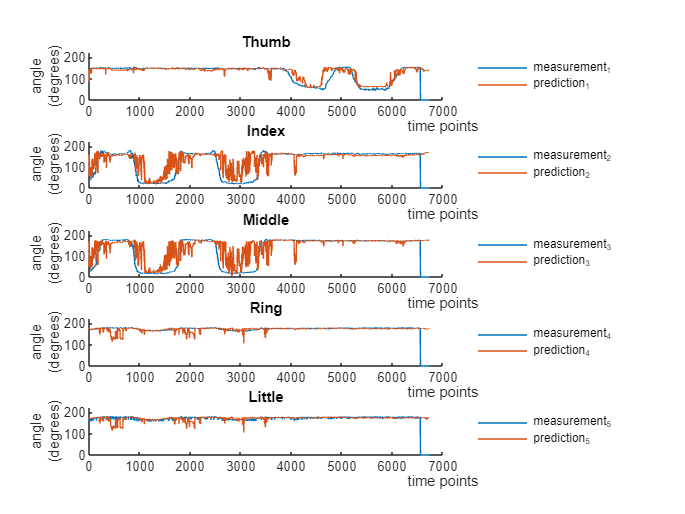

clf
figure
for i = 1:5
    subplot (5,1,i)
    hold on
    plot(test(:,i))
    plot(pred_raw(:,i))
%     plot(pred_filt(:,i))
%     plot(pred_env(:,i))
    ylim([0 225])
    legend("measurement_"+i, "prediction_"+i, ...
        'Location','eastoutside')
    legend('boxoff')
    xlabel('time points', 'Position', [7000 -75], 'HorizontalAlignment','center','VerticalAlignment','cap');
    ylabel({'angle'; '(degrees)'});
    title(fingers(i));
    hold off
end

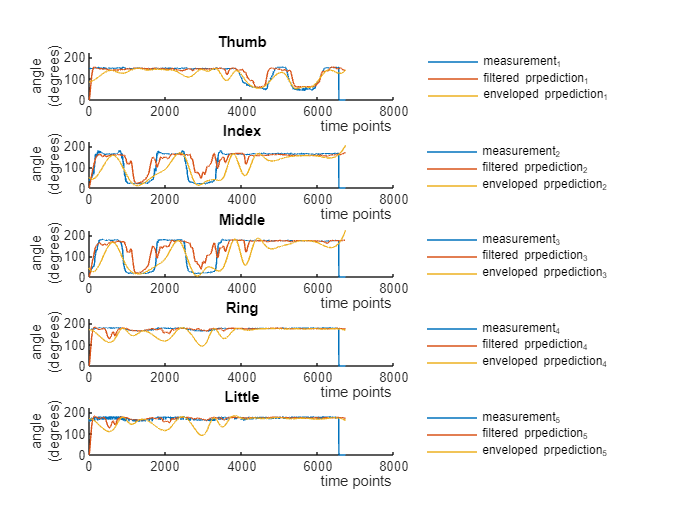

clf
figure
for i = 1:5
    subplot (5,1,i)
    hold on
    plot(test(:,i))
%     plot(pred_raw(:,i))
    plot(pred_filt(:,i))
    plot(pred_env(:,i))
    ylim([0 225])
    legend("measurement_"+i, "filtered prpediction_"+i, "enveloped prpediction_"+i, ...
        'Location','eastoutside')
    legend('boxoff')
    xlabel('time points', 'Position', [7000 -75], 'HorizontalAlignment','center','VerticalAlignment','cap');
    ylabel({'angle'; '(degrees)'});
    title(fingers(i));
    hold off
end